close all;clear all;
Fs = 48000;
test1 = load('Normal Baseline Data 12K/Normal_0_1797_rpm.mat'); % 29.95 Hz
freqRot = 29.95; % tours/min → Hz
acc=test1.X097_FE_time;
acc=acc(1:(48000*2));
speedMax = 50;
speedMin = 1;


plot

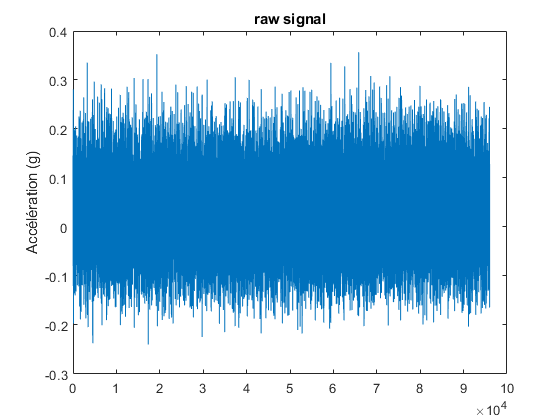

plot(acc)
ylabel('Accélération (g)')
title('raw signal')

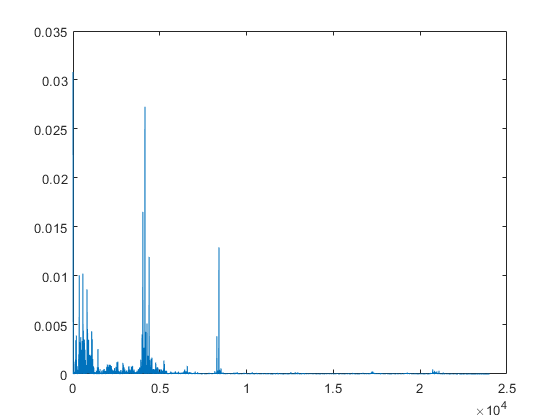

plotFFT(acc,Fs);

fonction

% Envelope Extraction
dec = 8;
acc = decimate(acc, dec, 8, 'fir');
Fs = Fs /dec;
signalEnvelope = getEnv(acc, Fs, 500);  %   extracts the envelope

% ACF Computation
autocorrelationFunction = getAcf(signalEnvelope);  %   computes the ACF
compare = acf_frame_fft(signalEnvelope, 6000);

opts = struct();
        opts.unbiased   = false;
        opts.normalize  = true;
        opts.window        = 'none' ;  % or "hann"
        opts.maxLagSec   = Inf;
        
[lags, compare2, info]= acf_fft_band(signalEnvelope, Fs, 100, 1,opts);

 % Variante non biaisée (comparaison robuste entre tailles de fenêtre) :
opts.unbiased = true;
[ lags, compare3 ] = acf_fft_band(signalEnvelope, Fs, 100,1, opts);

% Ajouter une fenêtre de Hann sur x (si fort leakage) :
opts.window = 'hann';
[ lags, compare4 ] = acf_fft_band(signalEnvelope, Fs, 100,1, opts);

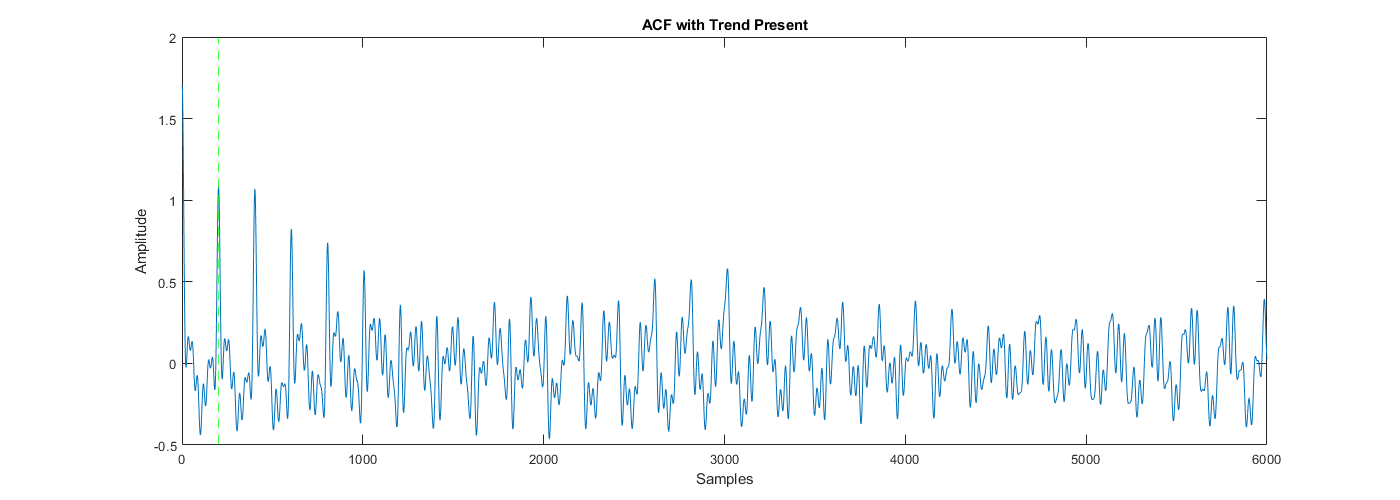


nsdf = McLeod(signalEnvelope , Fs ,speedMin ,speedMax);

% Plotting ACF with Trend
figureHandle = figure;
plot(autocorrelationFunction);
xline(Fs/freqRot, 'g--');  % Marking the frequency line
title('ACF with Trend Present');
xlabel('Samples');
ylabel('Amplitude');
set(figureHandle, 'Position', [100 100 1400 500]);  % Adjusting figure position and size

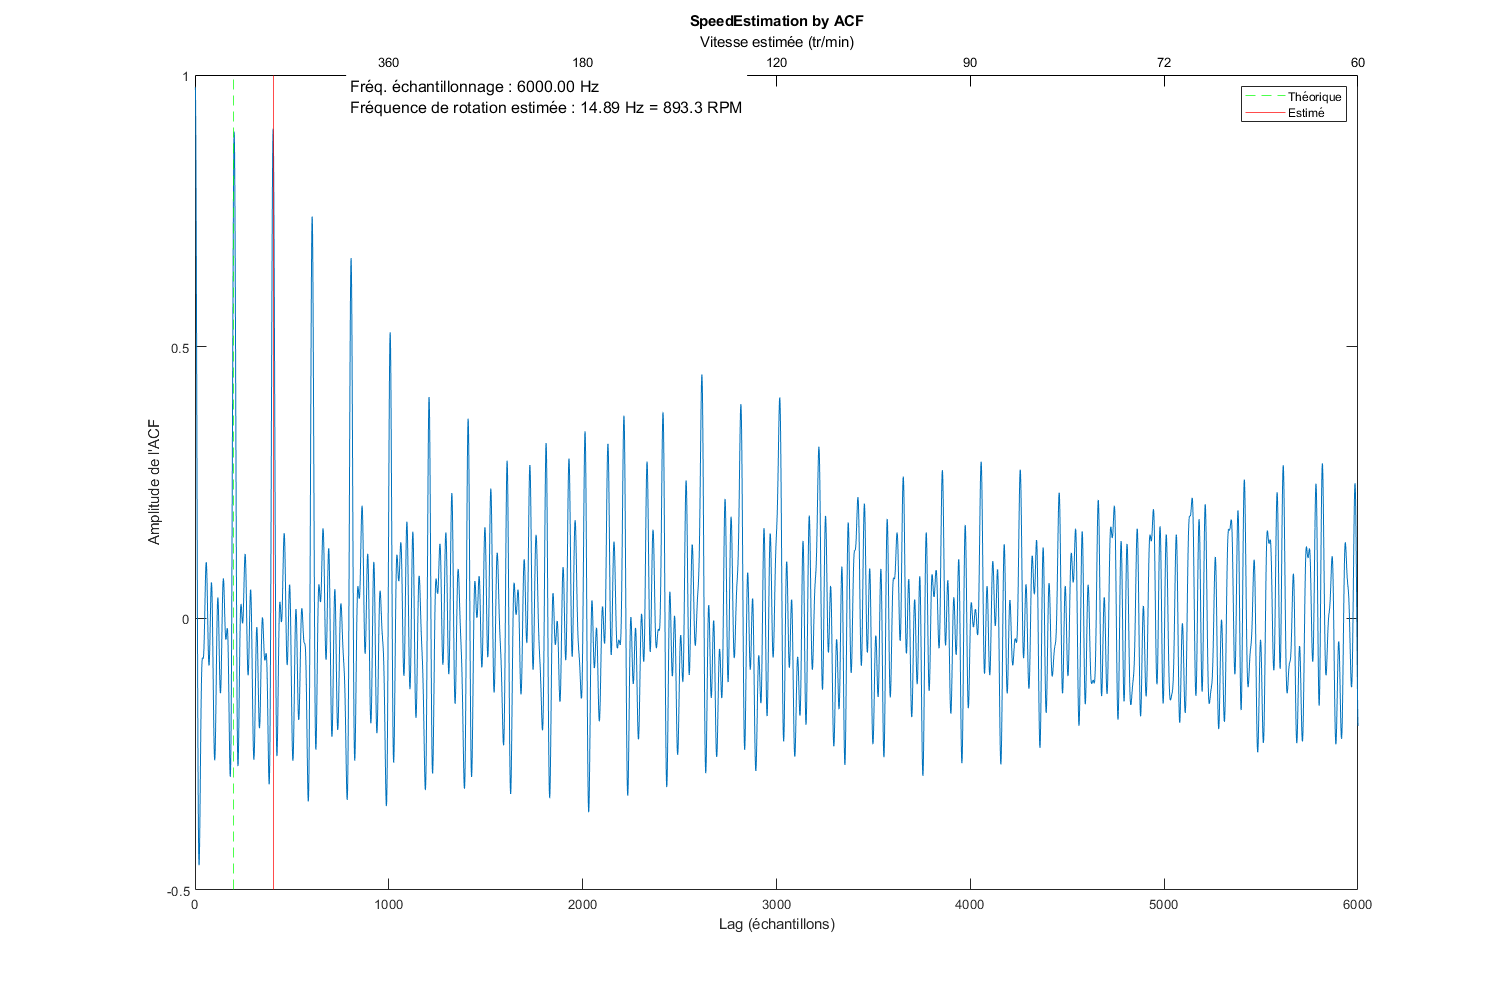

% Hodrick-Prescott Filter for Detrending ACF
% -------------------------------------------

% Initialize the autocorrelation function
acf = autocorrelationFunction;
Y = acf(:);

% Smoothing Parameter
% Note: The smoothing value should be in accordance with the sampling rate.
smoothing = 1e+6;

% Number of Observations
numObs = numel(acf);

% Constructing the Hodrick-Prescott Filter Coefficients
% Normally this would be a sparse matrix for efficiency, but here we use a full matrix.
e = repmat([smoothing, -4 * smoothing, (1 + 6 * smoothing), -4 * smoothing, smoothing], numObs, 1);
A = spdiags(e, -2:2, numObs, numObs);
% Adjusting the first and last rows of matrix A for boundary conditions
A(1,1) = 1 + smoothing;
A(1,2) = -2 * smoothing;
A(2,1) = -2 * smoothing;
A(2,2) = 1 + 5 * smoothing;
A(numObs-1, numObs-1) = 1 + 5 * smoothing;
A(numObs-1, numObs) = -2 * smoothing;
A(numObs, numObs-1) = -2 * smoothing;
A(numObs, numObs) = 1 + smoothing;

% LU Decomposition for Solving the Filter
% L for lower triangular matrix and U for upper triangular matrix
[L, U, P] = lu(A);

% Solving the System Using LU Decomposition
y = L \ (P * Y);  % Solving Ly = Pb using forward substitution
trend = U \ y;    % Solving Ux = y using backward substitution

% Detrending the ACF Signal
acfDetrended = Y - trend;  % Subtracting the trend component
% acfDetrended(1:round(Fs/speedMax)) = 0; 
% extrac the maximum
[pks, locs_idx] = findpeaks(acfDetrended, 'MinPeakProminence', 0.5);
[M,maxpeaksIdx]=max(pks);
T_rotation = locs_idx(maxpeaksIdx) / Fs;  % Temps entre deux tours (en secondes)
freq_rot_Hz = 1 / T_rotation;
rpm_estime = freq_rot_Hz * 60;



% Plotting the Detrended ACF
figureHandle = figure;
plot(acfDetrended);
xlabel('Lag (échantillons)');
ylabel('Amplitude de l''ACF');
% === Création de l'axe secondaire pour RPM (haut du graphe)
ax1 = gca;
ax1_pos = ax1.Position;

% Nouvel axe au-dessus
ax2 = axes('Position', ax1_pos,...
    'XAxisLocation','top',...
    'YAxisLocation','right',...
    'Color','none',...
    'XColor','k', 'YColor','none');

% Caler les ticks RPM sur les mêmes positions que les ticks de lag
xticks = get(ax1, 'XTick');
xticks_nozero = xticks; xticks_nozero(xticks_nozero == 0) = NaN;  % éviter div by zero
rpm_ticks = (60 * Fs) ./ xticks_nozero;  % RPM = 60 * Fs / lag

% Remplacer les inf/NaN par vide
rpm_labels = arrayfun(@(x) sprintf('%.0f', x), rpm_ticks, 'UniformOutput', false);
rpm_labels(isnan(rpm_ticks) | isinf(rpm_ticks)) = {''};

set(ax2, 'XLim', get(ax1, 'XLim'));
set(ax2, 'XTick', xticks);
set(ax2, 'XTickLabel', rpm_labels);
xlabel(ax2, 'Vitesse estimée (tr/min)');
% Ligne verte pour fréquence théorique
xline(Fs / freqRot, 'g--', 'DisplayName', 'Théorique');

% Ligne bleue pour le pic détecté dans l’ACF
xline(locs_idx(maxpeaksIdx), 'r', 'DisplayName', 'Estimé');
legend();  % Affiche la légende automatiquement
title('SpeedEstimation by ACF');
% === Infos
infoText = {
    sprintf('Fréq. échantillonnage : %.2f Hz', Fs)
    sprintf('Fréquence de rotation estimée : %.2f Hz = %.1f RPM\n', freq_rot_Hz, rpm_estime);
};
xPos = 800;
yPos = 4;  % ou ajuster selon le graphique
text(xPos, 1, infoText, 'VerticalAlignment', 'top', 'FontSize', 12, 'BackgroundColor', 'w');
set(figureHandle, 'Position', [100 100 1500 1000]);

plot

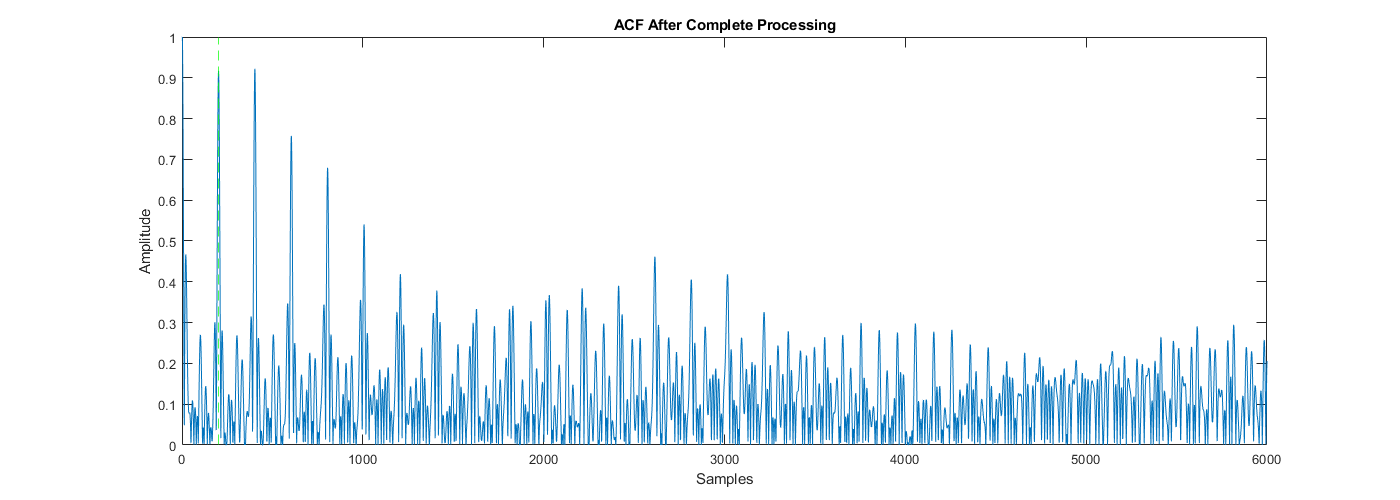



% Enhancing Peaks and Reducing Noise in Detrended ACF
% -----------------------------------------------------

% Median and Mean Absolute Deviation (MAD) Calculation
mu = median(acfDetrended);  % Median of the detrended ACF
s = mean(abs(acfDetrended - mu));  % Mean absolute deviation around the median

% Applying the Huber Function
% The Huber function is a robust method of scaling data. 
x = (acfDetrended' - mu) / s;
result = sign(x) .* min(abs(x), s);  % Applying Huber function to scale the data

% Applying the Huber Function Results to the ACF
acfHuber = acfDetrended' .* result;

% Normalization of ACF Between 0 and 1
% This normalization step makes the data more uniform and easier to analyze.
acfHuber = normalize_0_1(acfHuber);

% Plotting the Processed ACF
figureHandle = figure;
plot(acfHuber);
xline(Fs/freqRot, 'g--');  % Marking the frequency line
xlabel('Samples');
ylabel('Amplitude');
title('ACF After Complete Processing');
set(figureHandle, 'Position', [100 100 1400 500]);

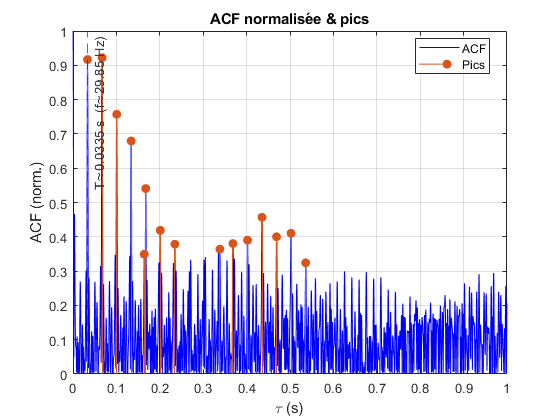

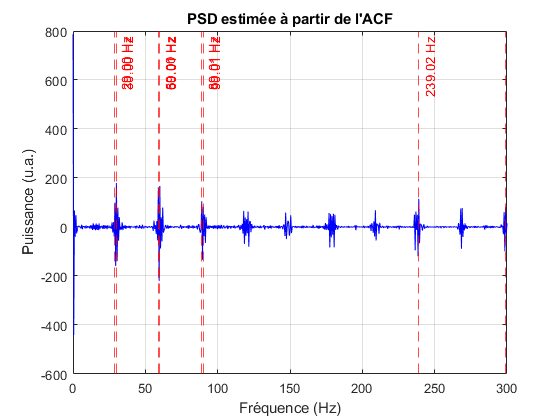


% analyse classique extract peak puis median des diff et analyse par fft Wiener–Khinchin (symétrisation puis Hann et enfin FFT)
R = analyze_acf_and_psd(acfHuber, Fs, ...
    'MaxLagSec', 1.0, ...        % fenêtre d'analyse de l'ACF (s)
    'TopPeaks', 15, ...          % nb max de pics pris pour le robust median
    'Prominence', 0.05, ...      % proéminence min (fraction de max ACF norm.)
    'SmoothMs', 2, ...           % lissage ACF (ms) avant détection de pics
    'PsdFmax', 300, ...          % borne d'affichage PSD (Hz)
    'ExportPrefix', '' );        % ex. 'resultats_acf' pour sauver PNG/CSV


disp('--- Résumé ---');

--- Résumé ---


fprintf('Période estimée  T ≈ %.6f s\n', R.period_s);

Période estimée  T ≈ 0.033500 s


fprintf('Fréquence       f ≈ %.3f Hz\n', R.f_hz);

Fréquence       f ≈ 29.851 Hz


fprintf('Vitesse         ≈ %.1f rpm\n', R.rpm);

Vitesse         ≈ 1791.0 rpm


fprintf('Vitesse ang.    ω ≈ %.2f rad/s\n', R.omega);

Vitesse ang.    ω ≈ 187.56 rad/s


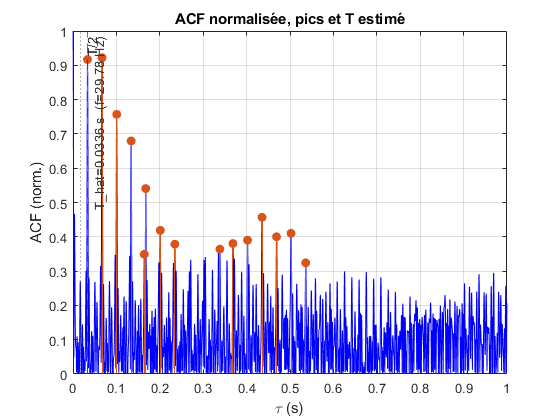

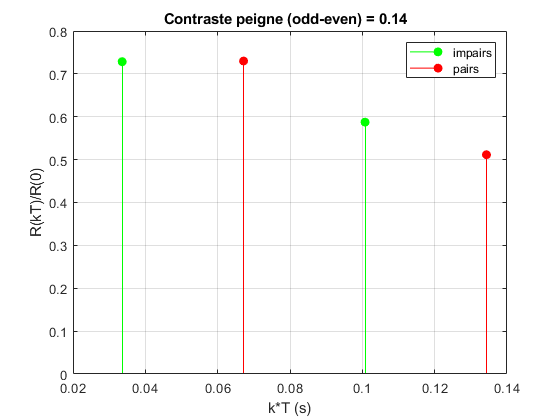

%“pics → médiane des intervalles + parabolique + anti-demi-tour (tests 𝑅(𝑇)R(T) vs 𝑅(𝑇/2)R(T/2) et peigne odd/even)”.
% 2) Paramètres de l'estimateur 1A
P = struct();
P.MaxLagSec   = 1.0;     % analyser l'ACF jusqu'à 1 s
P.SmoothMs    = 2;       % lissage avant détection de pics (ms)
P.Prominence  = 0.05;    % proéminence min (fraction du max hors lag 0)
P.TopPeaks    = 15;      % # pics max pour la médiane des intervalles
P.fmin        = 0.5;     % bande de recherche (Hz)
P.fmax        = 120;     % bande de recherche (Hz)
P.Kharm       = 4;       % # d'harmoniques pour le peigne odd/even
P.lambdaEven  = 0.8;     % pénalisation de l'énergie paire
P.gammaHalf   = 1.15;    % si R(T/2) > gamma*R(T) ET even>odd => demi-tour probable
P.Plot        = true;    % tracer les graphes

% 3) Estimation
[fr_hat, OUT] = estimate_fr_from_acf_1A(acfHuber, Fs, P);

% 4) Résumé
fprintf('\n--- Résultats 1A ---\n');


--- Résultats 1A ---


fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);

f_hat  = 29.777 Hz   (rpm ≈ 1786.6)


fprintf('omega  = %.2f rad/s\n', 2*pi*fr_hat);

omega  = 187.09 rad/s


fprintf('T_hat  = %.6f s\n', 1/max(fr_hat,eps));

T_hat  = 0.033583 s


fprintf('confidence(periodicity) ≈ %.2f (R(T)/R(0))\n', OUT.periodicity);

confidence(periodicity) ≈ 0.73 (R(T)/R(0))


fprintf('combContrast(odd-even) ≈ %.2f\n', OUT.combContrast);

combContrast(odd-even) ≈ 0.14


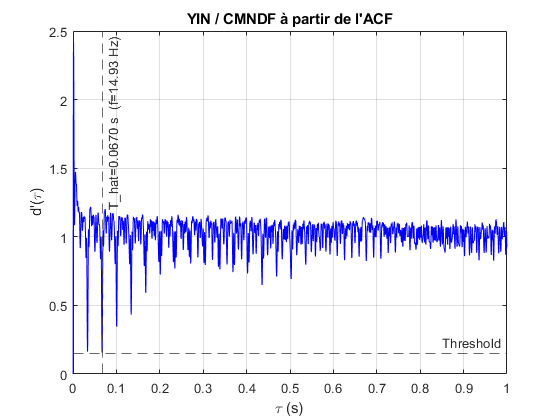

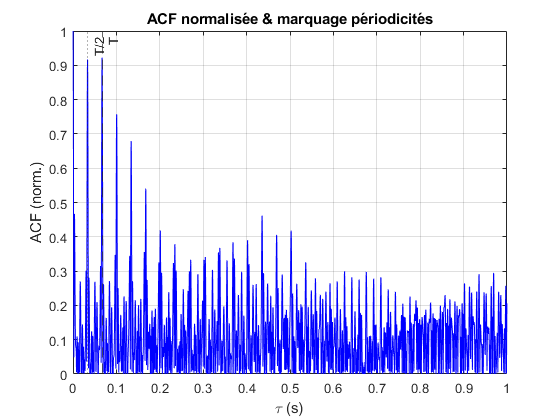

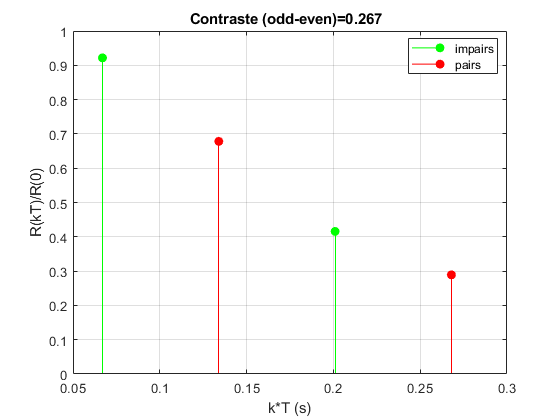

% 1B (ACF + YIN/CMNDF),

% 2) Paramètres YIN/CMNDF + anti-demi-tour
P = struct();
P.MaxLagSec   = 1.0;     % ACF analysée jusqu'à 1 s
P.fmin        = 0.5;     % Hz
P.fmax        = 120;     % Hz
P.Threshold   = 0.15;    % seuil YIN (0.1–0.2 typique)
P.SmoothMs    = 1.0;     % lissage (ms) de d' pour robustesse
P.Kharm       = 4;       % # harmoniques pour peigne odd/even
P.lambdaEven  = 0.8;     % pénalisation de l'énergie paire
P.gammaHalf   = 1.10;    % si R(T/2) > gamma*R(T) ET pairs>impairs => demi-tour probable
P.Plot        = true;

% 3) Estimation
[fr_hat, OUT] = estimate_fr_from_acf_1B(acfHuber, Fs, P);


% 4) Résumé
fprintf('\n--- Résultats 1B (YIN/CMNDF) ---\n');


--- Résultats 1B (YIN/CMNDF) ---


fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);

f_hat  = 14.928 Hz   (rpm ≈ 895.7)


fprintf('omega  = %.2f rad/s\n', 2*pi*fr_hat);

omega  = 93.79 rad/s


fprintf('T_hat  = %.6f s\n', 1/max(fr_hat,eps));

T_hat  = 0.066990 s


fprintf('YIN d''(T_hat) = %.3f (plus petit = meilleur)\n', OUT.dprime_T);

YIN d'(T_hat) = 0.157 (plus petit = meilleur)


fprintf('periodicity R(T)/R(0) ≈ %.3f\n', OUT.periodicity);

periodicity R(T)/R(0) ≈ 0.922


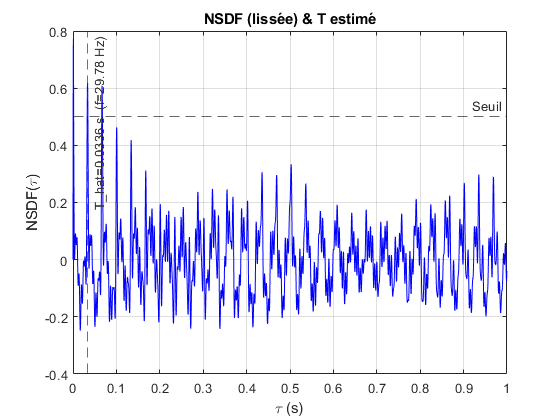

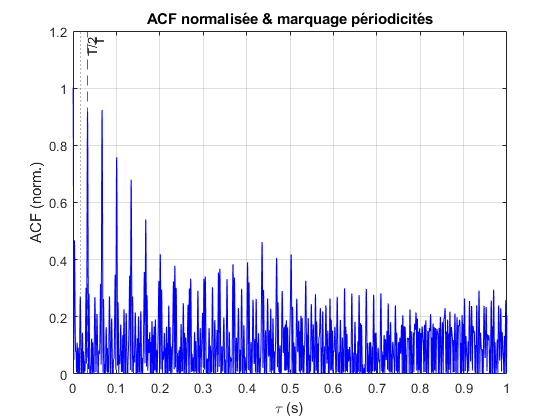

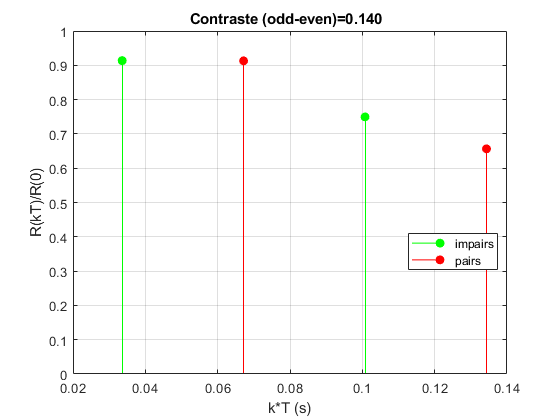

% 2) Paramètres NSDF / McLeod + anti-demi-tour
P = struct();
P.MaxLagSec   = 1.0;     % analyser l’ACF jusqu’à 1 s
P.fmin        = 0.5;     % Hz
P.fmax        = 120;     % Hz
P.MinNSDF     = 0.5;     % seuil de crête NSDF (0.4–0.8 typique)
P.SmoothMs    = 1.0;     % lissage léger (ms) de l’NSDF pour robustesse
P.PeakGuard   = 0.1;     % +/-10% autour de la 1ère crête pour l’interpolation
P.Kharm       = 4;       % # harmoniques pour peigne odd/even
P.lambdaEven  = 0.8;     % pénalisation de l’énergie paire
P.gammaHalf   = 1.10;    % critère demi-tour : R(T/2) > gamma*R(T) & pairs>impairs
P.ACFMode     = 'auto';  % 'auto'|'normalized'|'biased'|'unbiased' (si tu connais la normalisation)
P.Nproxy      = [];      % proxy de longueur signal si ACF 'biased/unbiased' (laisser [] sinon)
P.Plot        = true;

% 3) Estimation
[fr_hat, OUT] = estimate_fr_from_acf_1C(acfHuber, Fs, P, signalEnvelope);


% 4) Résumé
fprintf('\n--- Résultats 1C (NSDF/McLeod) ---\n');


--- Résultats 1C (NSDF/McLeod) ---


fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);

f_hat  = 29.777 Hz   (rpm ≈ 1786.6)


fprintf('omega  = %.2f rad/s\n', 2*pi*fr_hat);

omega  = 187.09 rad/s


fprintf('T_hat  = %.6f s\n', 1/max(fr_hat,eps));

T_hat  = 0.033583 s


fprintf('NSDF(T_hat) = %.3f   periodicity R(T)/R(0) ≈ %.3f\n', OUT.nsdf_T, OUT.periodicity);

NSDF(T_hat) = 0.618   periodicity R(T)/R(0) ≈ 0.914



%% --- Paramètres fenêtre glissante ---
WinSec  = 0.60;            % longueur fenêtre (s)
HopSec  = 0.20;            % pas temps entre fenêtres (s)
MaxLagS = min(0.80*WinSec, 1.0);   % ACF analysée jusqu'à 80% fenêtre, cap 1 s
fmin    = 0.5;             % Hz
fmax    = 120;             % Hz

% NSDF / McLeod + anti-demi-tour (par fenêtre)
P = struct();
P.MaxLagSec   = MaxLagS;
P.fmin        = fmin;
P.fmax        = fmax;
P.MinNSDF     = 0.55;      % crête NSDF min (0.4–0.8)
P.SmoothMs    = 1.0;       % lissage NSDF (ms)
P.PeakGuard   = 0.1;       % recherche fine ±10% de la crête
P.Kharm       = 4;         % peigne odd/even (k=1..K)
P.lambdaEven  = 0.8;       % pénalisation des pairs
P.gammaHalf   = 1.12;      % seuil demi-tour
P.ACFMode     = 'normalized'; % on normalise R(0)=1 par fenêtre
P.Nproxy      = [];        % (inutile ici)
P.Plot        = false;

% Kalman (état [f; fdot], discret, modèle vitesse constante)
KAL = struct();
KAL.dt     = HopSec;      % pas entre mesures
KAL.f0     = 20;          % init f (Hz)
KAL.fdot0  = 0;           % init dérivée (Hz/s)
KAL.sigma_fdot = 2.0;     % écart-type accélération (Hz/s)
KAL.sigma_meas = 0.8;     % écart-type mesure (Hz)
KAL.adapt_from_nsdf = true;% ajuste R selon la qualité NSDF
%% --- Tracking ---
[tt, f_meas, f_kal, diagFrames] = track_fr_nsdf_from_acf(acfHuber, Fs, WinSec, HopSec, P, KAL);

%% --- Visualisation ---
figure('Name','Tracking f_r(t)');
plot(tt, f_meas, '.-', 'DisplayName','mesure (NSDF/MPM)'); hold on; grid on;
plot(tt, f_kal,  'k-', 'LineWidth',1.5, 'DisplayName','Kalman lissé');
T  = 0,0333;

T = 0

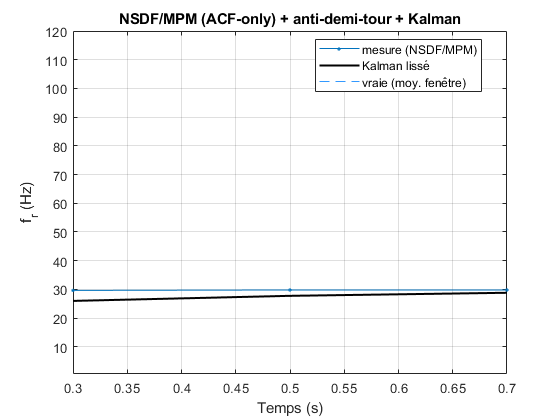

t  = (0:1/Fs:T-1/Fs).';
if all(~isnan(freqRot))
    % moyenne vraie dans chaque fenêtre
    fr_win = zeros(size(tt));
    for i=1:numel(tt)
        t0 = tt(i) - WinSec/2; t1 = t0 + WinSec;
        i0 = max(1, round(t0*Fs)+1); i1 = min(numel(t), round(t1*Fs));
        fr_win(i) = mean(freqRot(i0:i1));
    end
    plot(tt, fr_win, '--', 'Color',[0.2 0.6 1], 'DisplayName','vraie (moy. fenêtre)');
end
xlabel('Temps (s)'); ylabel('f_r (Hz)');
ylim([fmin fmax]); legend('Location','best');
title('NSDF/MPM (ACF-only) + anti-demi-tour + Kalman');

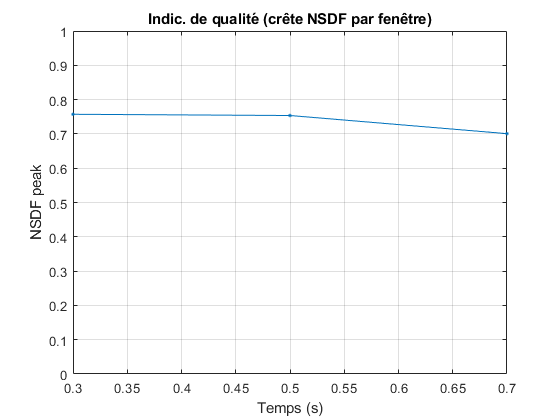


% (Optionnel) voir la qualité NSDF (crête) par fenêtre
q = arrayfun(@(d)d.nsdf_peak, diagFrames);
figure('Name','Qualité NSDF');
plot(tt, q, '.-'); grid on; xlabel('Temps (s)'); ylabel('NSDF peak'); ylim([0 1]);
title('Indic. de qualité (crête NSDF par fenêtre)');

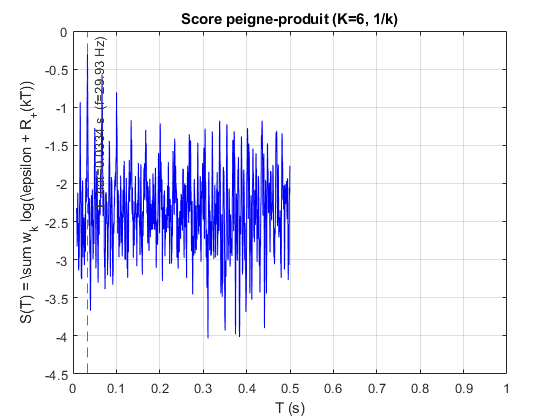

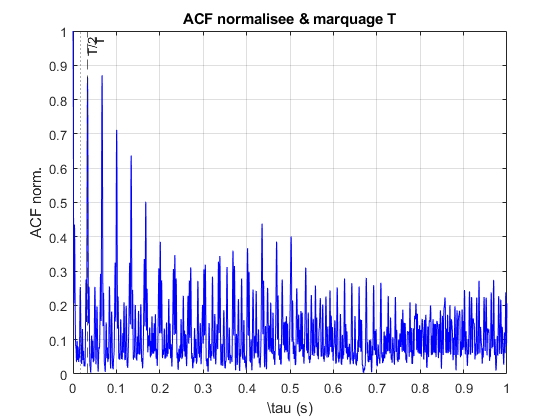

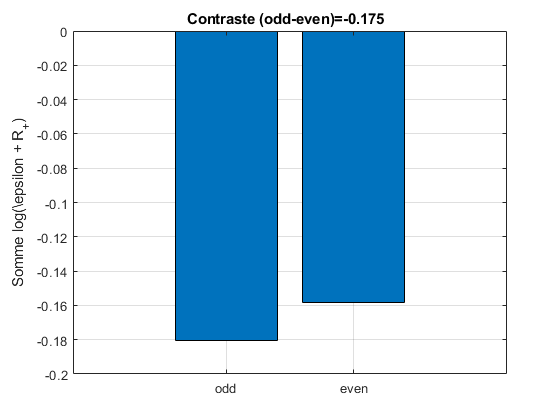

% 2) Parametres peigne-produit (log)
P = struct();
P.MaxLagSec   = 1.0;      % on analyse l'ACF jusqu'a 1 s
P.fmin        = 0.5;      % bande recherche (Hz)
P.fmax        = 120;      % bande recherche (Hz)
P.Kharm       = 6;        % nb d'harmoniques inclus dans le peigne
P.WeightMode  = '1/k';    % 'equal' ou '1/k'
P.Eps         = 1e-3;     % epsilon dans log( eps + R+ )
P.SmoothMs    = 1.0;      % lissage leger de l'ACF avant evaluation (ms)
P.PeakRefine  = true;     % interpolation parabolique sur S(T)
% Anti demi-tour :
P.lambdaEven  = 0.8;      % penalisation de l'energie paire
P.gammaHalf   = 1.12;     % si R(T/2) > gamma*R(T) ET pairs>impairs => demi-tour
P.Plot        = true;

% 3) Estimation Il construit un score de peigne à une période candidate T
[fr_hat, OUT] = estimate_fr_from_acf_1E(acfHuber, Fs, P);


% 4) Resume
fprintf('\n--- Resultats 1E (Peigne-produit log) ---\n');


--- Resultats 1E (Peigne-produit log) ---


fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);

f_hat  = 29.925 Hz   (rpm ≈ 1795.5)


fprintf('omega  = %.2f rad/s\n', 2*pi*fr_hat);

omega  = 188.03 rad/s


fprintf('T_hat  = %.6f s\n', 1/max(fr_hat,eps));

T_hat  = 0.033417 s


fprintf('periodicity R(T)/R(0) ≈ %.3f\n', OUT.periodicity);

periodicity R(T)/R(0) ≈ 0.861


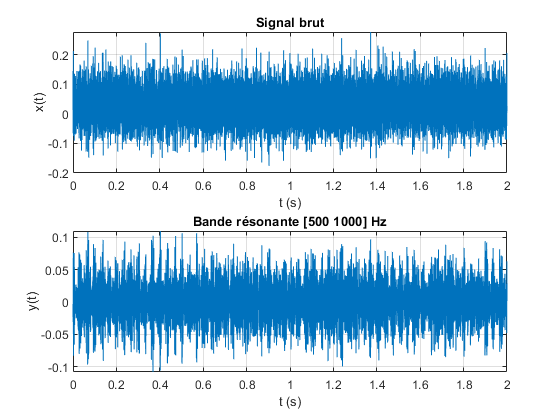

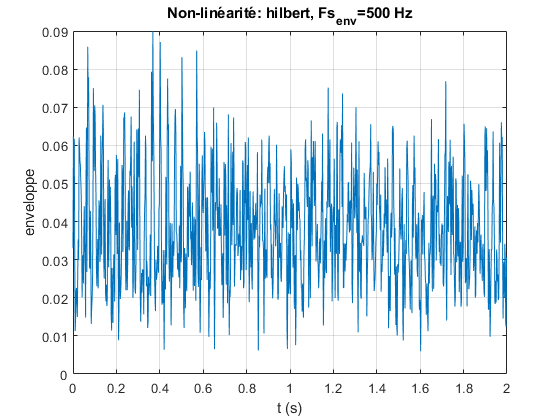

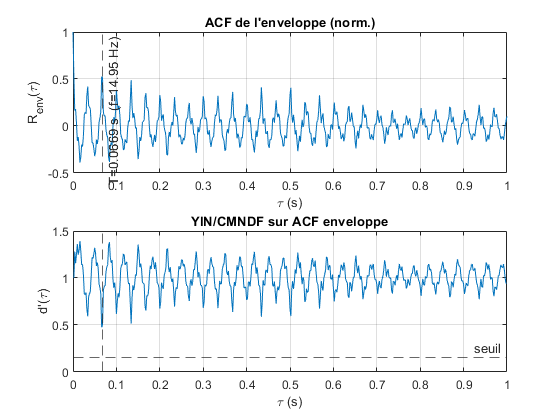

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Paramètres Solution F
P = struct();
% --- Bande résonante : auto (kurtosis) ou manuelle ---
P.bandMode    = 'manual';         % 'auto' ou 'manual'
P.searchBand  = [200 3000];     % Hz (pour l'auto)
P.nBands      = 18;             % nb sous-bandes (auto)
P.bandManual  = [500 1000];     % Hz (utilisé si bandMode='manual')
% --- Non-linéarité & enveloppe
P.nonlinearity= 'hilbert';     % 'halfwave' | 'abs' | 'power' | 'hilbert'
P.gamma       = 0.7;            % pour 'power' : |x|^gamma * sign(x)
P.envFs       = 500;            % Hz cible pour l'enveloppe (après décim.)
P.fmin        = 0.5;            % Hz, bande de recherche f_r
P.fmax        = 120;            % Hz
P.maxLagSec   = 1.0;            % s, ACF analysée
P.yinThresh   = 0.15;           % CMNDF seuil (YIN) 0.1–0.2 typique
P.smoothMs    = 1.0;            % ms : lissage léger NSDF/CMNDF
% --- Anti-demi-tour (sécurité, même si rectif aide déjà)
P.Kharm       = 4;              % nb d’harmoniques pour peigne odd/even
P.lambdaEven  = 0.8;            % pénalisation énergie paire
P.gammaHalf   = 1.12;           % critère R(T/2) > gamma*R(T)
P.plot        = true;
% Chaîne enveloppe avant ACF differente facon de calculer l'enveloppe
[fr_hat, OUT] = estimate_fr_envelope_acf_F(acc, Fs, P);


fprintf('\n--- Résultats Solution F ---\n');


--- Résultats Solution F ---


fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);

f_hat  = 14.950 Hz   (rpm ≈ 897.0)


fprintf('omega  = %.2f rad/s\n', 2*pi*fr_hat);

omega  = 93.93 rad/s


fprintf('T_hat  = %.6f s\n', 1/max(fr_hat,eps));

T_hat  = 0.066891 s


fprintf('R_env(T)/R_env(0) ≈ %.3f, NSDF_peak≈%.3f\n', OUT.periodicity, OUT.nsdf_T);

R_env(T)/R_env(0) ≈ 0.519, NSDF_peak≈0.758


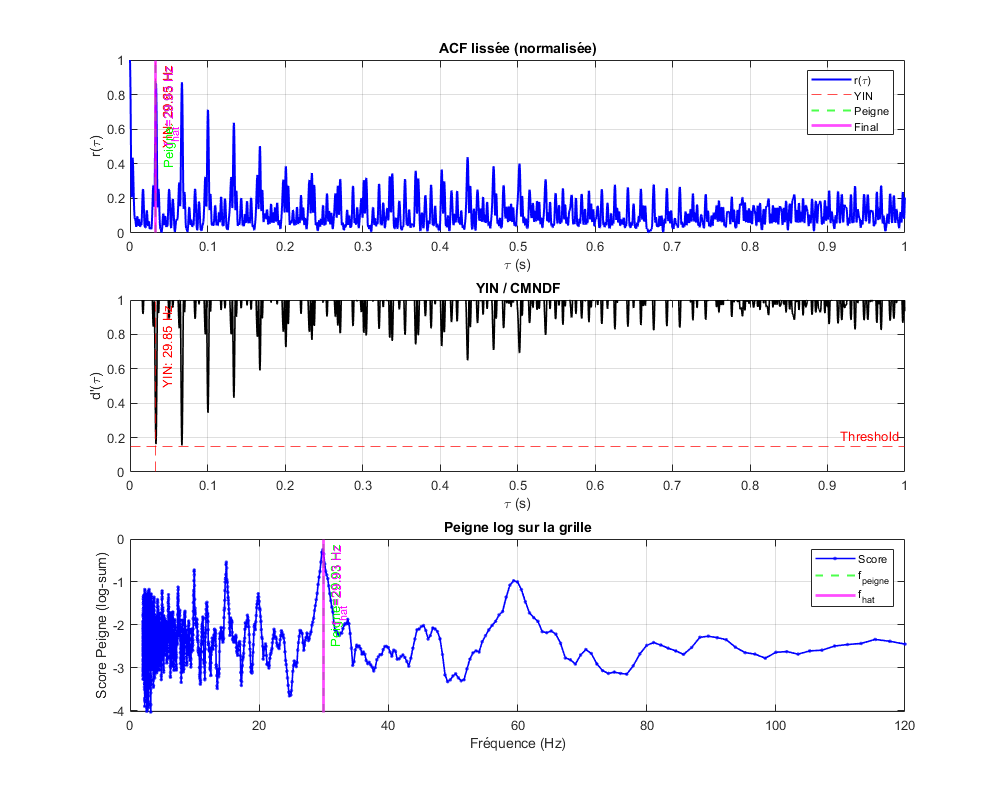


% --- Paramètres 1G ---
acf_frames= x(:);
tFrames = 0.5;   % => 0.5 s

P = struct();
P.fmin = 0.5;            % Hz
P.fmax = 120;            % Hz
P.maxLagSec = 1.0;       % s analysées dans l'ACF (borne supérieure)
% Mesure par frame (YIN/CMNDF-from-ACF)
P.yinThresh = 0.15;
P.smoothMs  = 1.0;
% Emission HMM (peigne log)
P.Kharm       = 5;
P.WeightMode  = '1/k';   % 'equal' ou '1/k'
P.Eps         = 1e-3;
% Transition HMM (sur grille de tau)
P.gridStepSamp = 1;      % pas de grille en échantillons de lag
P.maxJumpBins  = 6;      % transitions limitées à ±6 bins/frame
P.sigmaTrans   = 2.0;    % coût ~ (Δbins)^2/(2*sigma^2)
P.octavePenalty= 6.0;    % surcoût si (quasi) demi/double période
% Kalman sur tau
P.kalman_dt     = [];    % si vide, déduit de tFrames sinon = 1 (frames unitaires)
P.kal_sigma_taudot = 5e-3; % (s/s) ~ dérivée de période (régularisation)
P.kal_sigma_meas   = 1.5e-3; % incertitude mesure tau (s)
% Divers/plots
P.plot = true;

% --- Tracking 1G ---
[f_hat, f_yin, f_peigne, OUT] = estimate_from_acf_oneframe(acfHuber, Fs, P);

% PLOT_ESTIMATE_FROM_ACF
% Visualisation des sorties de estimate_from_acf_oneframe
%
% Entrées :
%   OUT      : struct de diagnostics (retourné par estimate_from_acf_oneframe)
%   Fs       : fréquence d'échantillonnage [Hz]
%   f_hat    : fréquence finale choisie [Hz]
%   f_yin    : fréquence estimée par YIN [Hz]
%   f_peigne : fréquence estimée par Peigne [Hz]

tau = (0:numel(OUT.r_eval)-1).' / Fs;   % axe des lags en secondes
freqGrid = Fs ./ OUT.grid;              % grille fréquence (peigne)

figure('Name','Analyse ACF (une frame)','Color','w','Position',[100 100 1000 800]);

% -------------------------------------------------------------------------
% 1) ACF lissée
subplot(3,1,1);
plot(tau, OUT.r_eval, 'b-', 'LineWidth',1.5); hold on; grid on;
xlabel('\tau (s)'); ylabel('r(\tau)');
title('ACF lissée (normalisée)');
xline(OUT.T_yin,    'r--', sprintf('YIN: %.2f Hz',     f_yin));
xline(OUT.T_peigne, 'g--', sprintf('Peigne: %.2f Hz',  f_peigne), 'LineWidth', 1.5);
xline(1/f_hat,      'm-',  sprintf('f_{hat}=%.2f Hz',  f_hat),    'LineWidth', 2);
legend('r(\tau)','YIN','Peigne','Final');

% -------------------------------------------------------------------------
% 2) CMNDF (YIN)
subplot(3,1,2);
tt = (1:numel(OUT.dprime)).'/Fs;   % tau index -> secondes
plot(tt, OUT.dprime, 'k-', 'LineWidth',1.2); hold on; grid on;
yline(OUT.params.yinThresh, 'r--', 'Threshold');
xlabel('\tau (s)'); ylabel('d''(\tau)');
title('YIN / CMNDF');
xline(OUT.T_yin, 'r--', sprintf('YIN: %.2f Hz', f_yin));
ylim([0 1]);

% -------------------------------------------------------------------------
% 3) Score Peigne
subplot(3,1,3);
plot(freqGrid, OUT.Score, 'b.-', 'LineWidth',1.2); hold on; grid on;
xlabel('Fréquence (Hz)'); ylabel('Score Peigne (log-sum)');
title('Peigne log sur la grille');
xline(f_peigne, 'g--', sprintf('Peigne=%.2f Hz', f_peigne), 'LineWidth', 1.5);
xline(f_hat,    'm-',  sprintf('f_{hat}=%.2f Hz', f_hat),   'LineWidth', 2);
legend('Score','f_{peigne}','f_{hat}');

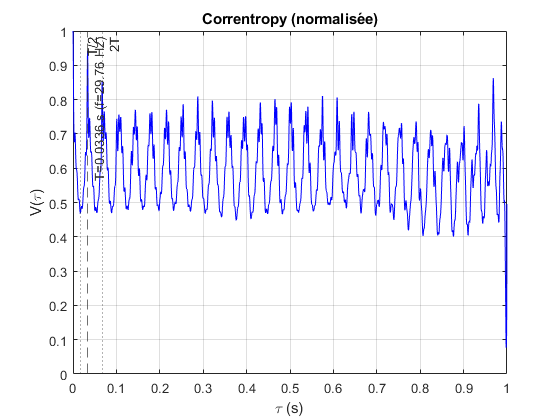

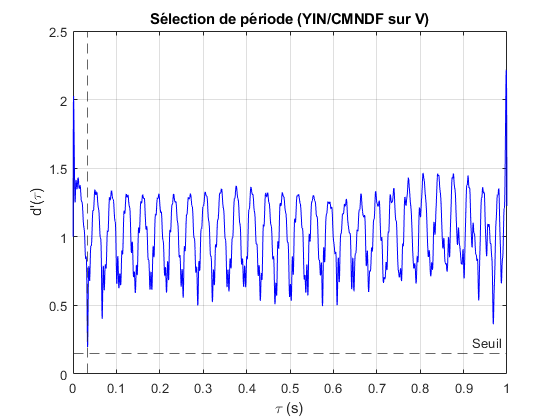

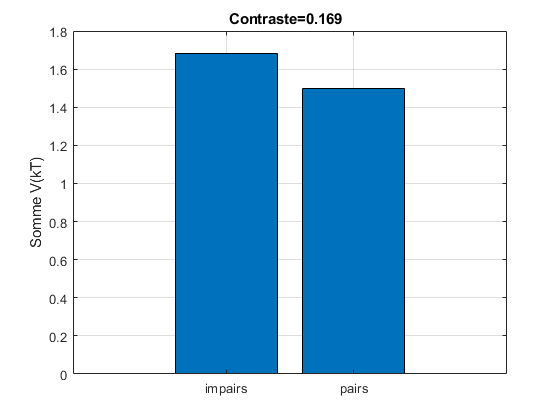


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2) Paramètres (valeurs sûres par défaut)
P = struct();
P.MaxLagSec   = 1.0;       % ACF analysée jusqu'à 1 s
P.fmin        = 0.5;       % bande de recherche (Hz)
P.fmax        = 120;       % bande de recherche (Hz)
% --- Correntropy ---
P.sigmaMode   = 'mad';     % 'mad' | 'silverman' | 'fixed' (pour le signal x)
P.sigma       = [];        % si 'fixed', donne la valeur (en unités de x)
P.sigmaProxy  = 0.25;      % si ACF-only: largeur proxy (adim.) pour K(r)=exp(-(1-r)/sigmaProxy^2)
% --- Sélection de période (YIN/CMNDF-like sur correntropy) ---
P.Threshold   = 0.15;      % seuil CMNDF 0.1–0.2
P.SmoothMs    = 1.0;       % lissage léger (ms)
% --- Anti demi-tour ---
P.Kharm       = 4;         % peigne impairs/pairs
P.lambdaEven  = 0.8;
P.gammaHalf   = 1.12;
P.Plot        = true;

% ici Cross entropie trés interressant
[fr_hat, OUT] = estimate_fr_correntropy_1H(Fs, P, 'x', nsdf);

% 4) Résumé
fprintf('\n--- Résultats 1H (Correntropy) ---\n');


--- Résultats 1H (Correntropy) ---


fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);

f_hat  = 29.756 Hz   (rpm ≈ 1785.4)


fprintf('omega  = %.2f rad/s\n', 2*pi*fr_hat);

omega  = 186.97 rad/s


fprintf('T_hat  = %.6f s\n', 1/max(fr_hat,eps));

T_hat  = 0.033606 s


fprintf('V(T)/V(0) ≈ %.3f ; NSDF-like peak ≈ %.3f\n', OUT.periodicity, OUT.nsdf_like_T);

V(T)/V(0) ≈ 0.942 ; NSDF-like peak ≈ 0.802




% 4) Résumé
fprintf('\n--- Résultats 1H (Correntropy) ---\n');


--- Résultats 1H (Correntropy) ---


fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);

f_hat  = 29.756 Hz   (rpm ≈ 1785.4)


fprintf('omega  = %.2f rad/s\n', 2*pi*fr_hat);

omega  = 186.97 rad/s


fprintf('T_hat  = %.6f s\n', 1/max(fr_hat,eps));

T_hat  = 0.033606 s


fprintf('V(T)/V(0) ≈ %.3f ; NSDF-like peak ≈ %.3f\n', OUT.periodicity, OUT.nsdf_like_T);

V(T)/V(0) ≈ 0.942 ; NSDF-like peak ≈ 0.802


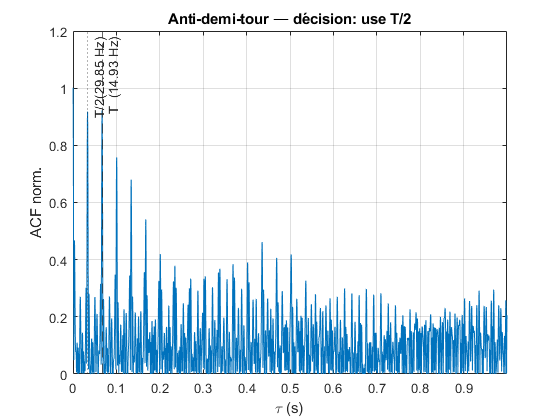

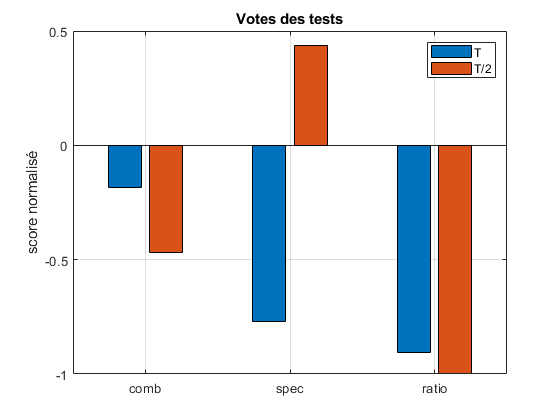


% --- Candidat initial T_cand (si tu en as déjà un, remplace cette partie) ---
% Ici on fabrique un candidat avec YIN/CMNDF-from-ACF (rapide)
T_cand = initial_candidate_T_from_acf(acfHuber(:), Fs, 1, 50);

% --- Paramètres de la stratégie anti-demi-tour ---
P = struct();
P.Kharm        = 5;        % nb d'harmoniques
P.WeightMode   = '1/k';    % 'equal' ou '1/k'
P.lambdaEven   = 0.8;      % pénalisation des pairs
P.gammaHalf    = 1.12;     % seuil R(T/2) > gamma*R(T)
P.UseLogComb   = true;     % peigne produit (log) en plus du peigne somme
P.SpecBW_Hz    = 1.0;      % demi-largeur (Hz) pour l'énergie spectrale autour de k*f0
P.wComb        = 0.45;     % poids vote peigne ACF (odd-even)
P.wSpec        = 0.40;     % poids vote spectre (odd-even)
P.wRratio      = 0.15;     % poids vote ratio R(T) vs R(T/2)
P.considerDouble = false;  % si true, compare aussi 2T
P.Plot         = true;

% --- Décision fusion tri-critères (ACF-peigne, spectral-peigne, ratio ACF), pondérée et diagnostiquée, avec option 2T.
% C'est nettement plus robuste aux cas tordus (motifs bi-lobes, rectification, harmoniques forts, bruit, aliasing doux).
[f_corr, DEC] = anti_demi_tour_acf(acfHuber(:), Fs, T_cand, P);


% --- Résumé ---
fprintf('\n--- Anti-demi-tour (ACF-only) ---\n');


--- Anti-demi-tour (ACF-only) ---


fprintf('f_candidat = %.3f Hz   ->   f_corrigé = %.3f Hz\n', Fs/T_cand, f_corr);

f_candidat = 89562.333 Hz   ->   f_corrigé = 29.854 Hz


fprintf('Scores: comb=%.3f, spec=%.3f, ratio=%.3f  (T vs T/2)\n', DEC.sComb, DEC.sSpec, DEC.sRatio);

Scores: comb=-0.185, spec=-0.471, ratio=-0.769  (T vs T/2)
Scores: comb=0.436, spec=-0.905, ratio=-1.000  (T vs T/2)


fprintf('Décision: %s\n', DEC.decisionStr);

Décision: use T/2


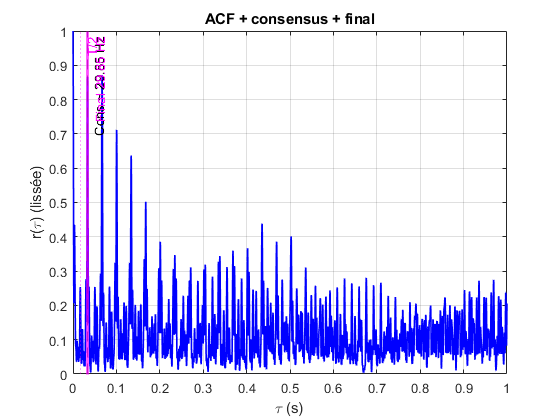

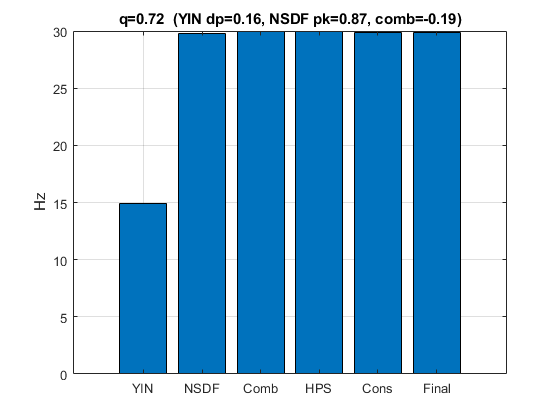

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tFrames = [];
A = acfHuber(:);        % un seul frame
% Paramètres
P = struct();
% Bande utile (rotation)
P.fmin = 0.5; P.fmax = 120;         % Hz
P.maxLagSec = 1.0;                  % ACF analysée jusqu’à 1 s
% Recherche candidats
P.SmoothMs   = 1.0;                 % ms (lissage léger ACF)
P.YIN_thresh = 0.15;                % CMNDF seuil
P.NSDF_min   = 0.55;                % crête mini NSDF
P.Comb_K     = 6;                   % # harmoniques peigne-produit
P.Comb_eps   = 1e-3;                % eps dans log
P.Comb_weight= '1/k';               % poids peigne ('equal' ou '1/k')
P.HPS_use    = true;                % utiliser HPS sur PSD issue ACF
P.HPS_K      = 4;                   % # harmoniques HPS
P.HPS_dfHz   = 0.1;                 % pas Hz pour HPS
% Anti-demi-tour
P.lambdaEven = 0.8;                 % pénalisation pairs
P.gammaHalf  = 1.12;                % R(T/2) > gamma*R(T)
P.UseLogComb = true;                % peigne ACF en log-somme
P.SpecBW_Hz  = 1.0;                 % demi-largeur bande (Hz) pour énergie PSD
P.wComb      = 0.45; P.wSpec = 0.40; P.wRratio = 0.15; % poids vote
P.considerDouble = false;           % comparer aussi 2T (option)
% Kalman
P.kal_dt         = [];              % si vide, déduit de tFrames
P.kal_sigma_fdot = 2.0;             % Hz/s (dynamique)
P.kal_sigma_meas = 0.8;             % Hz (mesure de base)
P.kal_adapt_from_quality = true;    % adapter R avec qualité
% Divers
P.Plot = true;

% [tF, f_meas, f_kal, DIAG] = track_glissant_anti_half_acf(A, Fs, tFrames, P);
[f_final, OUT] = track_oneframe_anti_half_acf(acfHuber(:), Fs, P);


% ---- Affichage console ----
fprintf('=== Résultats estimation (1 frame) ===\n');
fprintf('Final      : %.2f Hz\n', f_final);
fprintf(' - YIN     : %.2f Hz (dp=%.3f)\n', OUT.fyin, OUT.yin_dp);
fprintf(' - NSDF    : %.2f Hz (pk=%.3f)\n', OUT.fnsdf, OUT.nsdf_pk);
fprintf(' - CombLog : %.2f Hz\n', OUT.fcomb);
fprintf(' - HPS     : %.2f Hz\n', OUT.fhps);
fprintf('Consensus  : %.2f Hz\n', OUT.f_cons);
fprintf('Qualité q  : %.2f (0 mauvais..1 excellent)\n', OUT.q);

=== Résultats estimation (1 frame) ===


Final      : 29.85 Hz


 - YIN     : 14.93 Hz (dp=0.155)


 - NSDF    : 29.78 Hz (pk=0.866)


 - CombLog : 29.93 Hz


 - HPS     : 29.95 Hz


Consensus  : 29.85 Hz


Qualité q  : 0.72 (0 mauvais..1 excellent)


Cannot find an exact (case-sensitive) match for 'tF'

The closest match is: tf in C:\Program Files\Polyspace\R2020a\toolbox\control\ctrlmodels\@tf\tf.m

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Profil “MCU” (opérations simples, K=3 harmoniques, peu de divisions)
P = struct();
P.fmin = 0.5; P.fmax = 120;    % bande recherche
P.maxLagSec = 1.0;             % borne ACF analysée
P.minProm   = 0.05;            % proéminence min (relatif au max hors lag0)
P.smoothN   = 3;               % lissage ACF (moy. mobile) — 1,2,3 échantillons
P.minPkDist = [];              % distance min entre pics (auto si vide)
P.Kharm     = 3;               % # harmoniques pour le peigne odd/even
P.gammaHalf = 1.15;            % seuil R(T/2) > gamma*R(T)
P.lambdaEven= 0.85;            % pénalisation énergie paire
P.roundMult = true;            % (MCU) évaluer k*T au plus proche échantillon (pas d’interp)
P.parabolic = true;            % petite interp. parabolique locale (désactivable sur MCU)
P.Plot      = true;            % tracés de validation PC

[fr_hat, OUT] = reco_mcu_acf(acfHuber(:), Fs, P);

fprintf('\n--- Reco MCU (ACF-only) ---\n');
fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);
fprintf('T_hat  = %.6f s   periodicity=%.3f   q=%.2f\n', OUT.T_hat, OUT.periodicity, OUT.q);







- **DC removed** : indispensable (sinon le pic à lag 0 écrase tout, surtout pour des enveloppes).

- **Zero-padding ≥ 2L−1** : garantit une **ACF linéaire** (pas circulaire).

- **Unbiased option** : utile si tu compares des fenêtres de **longueurs différentes**.

- **Bande ****[****f****min**** ****,****f****max**** ****]****[f_{\min}, f_{\max}]****[****f****m****i****n****�****,****f****m****a****x****�****]** convertie en lags [τmin ,τmax ][\tau_{\min}, \tau_{\max}][τmin�,τmax�] pour ne garder que ce qui est **physiquement plausible** pour ta tâche.

- **Normalize** : pratique pour comparer l’ACF entre frames / signaux (acf(0)=1).


function [lags, acf, info] = acf_fft_band(x, Fs, fmin, fmax, opts)
% ACF_FFT_BAND  Autocorrelation (FFT-based, linear) limited to [fmin..fmax]
% 
% [lags, acf, info] = acf_fft_band(x, Fs, fmin, fmax, opts)
% 
% Inputs:
%   x     : signal (vector)
%   Fs    : sampling rate [Hz]
%   fmin  : lowest fundamental of interest [Hz]   (sets tauMax)
%   fmax  : highest fundamental of interest [Hz]  (sets tauMin)
%   opts  : struct with optional fields:
%           .unbiased  (logical, default=false)  % divide each lag by (L-k)
%           .normalize (logical, default=true)   % acf(0)=1
%           .window    ('none'|'hann', default='none') % window on x
%           .maxLagSec (scalar, optional)        % extra upper cap in seconds
%
% Outputs:
%   lags  : vector of lags [samples], starting at tauMin..tauMax
%   acf   : ACF(tau) aligned with lags
%   info  : struct with fields:
%           .tauMinSamp, .tauMaxSamp, .L, .nfft
%
% Notes:
% - Removes DC (mean) before FFT.
% - Uses zero-padding >= 2L-1 for LINEAR ACF (not circular).
% - Use unbiased=true if you want comparability across window sizes.

%     arguments
%         x (:,1) double
%         Fs (1,1) double {mustBePositive}
%         fmin (1,1) double {mustBePositive}
%         fmax (1,1) double {mustBePositive}
%         opts.unbiased  logical = false
%         opts.normalize logical = true
%         opts.window    char    = 'none'   % or "hann"
%         opts.maxLagSec double  = Inf
%     end

    % --- pre
    x = x(:);
    L = numel(x);
    if fmax >= Fs/2
        warning('fmax >= Fs/2; setting fmax = 0.45*Fs'); 
        fmax = 0.45*Fs;
    end
    if fmin <= 0
        error('fmin must be > 0');
    end
    if fmax >= fmin
        warning('fmax >= fmin; swapping to enforce fmax < fmin.');
        tmp = fmax; fmax = fmin; fmin = tmp;
    end

    % --- tau bounds from band
    tauMinSamp = max(1, floor(Fs / fmax));             % smallest lag we trust
    tauMaxBand = floor(Fs / fmin);                      % largest lag from fmin
    tauMaxUser = min(L-1, floor(opts.maxLagSec * Fs));  % user/size cap
    tauMaxSamp = min([tauMaxBand, tauMaxUser, L-1]);

    if tauMinSamp > tauMaxSamp
        % Degenerate band -> fall back to [1 .. min(ceil(L/2), L-1)]
        tauMinSamp = 1;
        tauMaxSamp = min(ceil(L/2), L-1);
        warning('Band limits collapsed; using fallback tau range [%d..%d].', ...
                 tauMinSamp, tauMaxSamp);
    end

    % --- optional window on x (avoid strong edge effects if needed)
    switch lower(opts.window)
        case 'hann'
            w = hann(L);
            xw = (x - mean(x)) .* w;
        otherwise
            xw = x - mean(x);   % remove DC is crucial
    end

    % --- FFT-based linear ACF
    nfft = 2^nextpow2(2*L - 1);
    X = fft(xw, nfft);
    S = X .* conj(X);
    r = ifft(S, 'symmetric');   % linear ACF thanks to zero-padding
    r = r(1:L);                 % lags >= 0

    % --- biased / unbiased
    if opts.unbiased
        k = (0:L-1).';
        denom = max(L - k, 1);
        r = r ./ denom;
    end

    % --- normalization (so acf(0)=1)
    if opts.normalize
        r0 = max(r(1), eps);
        r = r / r0;
    end

    % --- crop to banded lags [tauMinSamp .. tauMaxSamp]
    lags = (tauMinSamp:tauMaxSamp).';
    acf  = r(lags + 1);   % +1 because r(1) is lag 0

    % --- info
    info = struct('tauMinSamp',tauMinSamp, 'tauMaxSamp',tauMaxSamp, ...
                  'L',L, 'nfft',nfft, 'fmin',fmin, 'fmax',fmax);
end

% ====== ACF (FFT-based, normalisée) ======
function acf = acf_frame_fft(xw, maxLag)
% ACF rapide (non biaisée approx.) via FFT sur fenêtre locale
xw = xw(:) - mean(xw); % 1) retire la moyenne (autocovariance)
L  = numel(xw);
nfft = 2^nextpow2(2*L-1);% 2) zero-padding à >= (2L-1) → ACF linéaire
X = fft(xw, nfft);
S = X .* conj(X);           % 3) |FFT|^2 (périodogramme)
r = ifft(S, 'symmetric');   % 4) IFFT réelle (évite le bruit imaginaire)
r = r(1:L);                 % 5) garde les lags ≥ 0 (0..L-1)
% normalisation
acf = r / max(r(1), eps);   % 6) normalise pour acf(0)=1
acf = acf(1:maxLag+1);      % 7) tronque à maxLag
end

function nsdf = McLeod(x , Fs ,fmin ,fmax)
x = x(:);
N  = numel(x);
% ---------- bornes de recherche ----------
tauMaxSamp = min(N-2, ceil(Fs / fmin));
% ===== Mode exact (McLeod) depuis x =====

tauIdx = (1:tauMaxSamp).';
nsdf = zeros(tauMaxSamp,1);
% précompute énergies cumulées
x2  = x.^2;
E   = cumsum(x2);           % E[k] = sum_{n=1..k} x[n]^2
E0  = E(end);               % énergie totale
for i=1:numel(tauIdx)
    T = tauIdx(i);
    M = N - T;
    if M <= 0, break; end
    % num = 2 * sum_{n=T+1..N} x[n] x[n-T]
    num = 2 * sum( x(1+T:N) .* x(1:N-T) );
    % denom = sum_{n=1..N} x[n]^2 + sum_{n=T+1..N} x[n-T]^2 = E0 + E[N-T]
    denom = E0 + E(N-T);
    nsdf(i) = num / max(denom, eps);
end
% pad à la taille affichage
nsdf = [0; nsdf];  %#ok<AGROW>
end

function info = parseFilename(filename)
    [~, name, ~] = fileparts(filename);
    parts = strsplit(name, '_');
    info.TypeMachine = parts{1};
    info.NomMachine = parts{2};
%     info.PointMesure = parts{3};
%     info.TypeMesure = parts{4};
    info.VitesseRPM = str2double(parts{end});
    info.FreqRotationHz = info.VitesseRPM / 60;
end

function [time, acc] = loadVibrationData(filepath)
    data = readmatrix(filepath, 'Delimiter', '\t');
    data = data(~all(isnan(data), 2), :);             % Retirer lignes vides
    data = data(:, any(~isnan(data)));                % Retirer colonnes vides
    time = data(:, 1);
    acc  = data(:, 2);
end

function Fs = estimateSamplingRate(time)
    N = length(time);
    duration = time(end) - time(1);
    Fs = (N - 1) / duration;
end

function durations = mergeCloseDurations(durations, threshold)
    i = 1;
    while i < length(durations)
        if durations(i) < threshold
            % Merge close durations
            if i < length(durations) - 1
                durations(i + 1) = durations(i + 1) + durations(i);
            end
            durations(i) = [];  % Remove current duration
        else
            i = i + 1;
        end
    end
end

function isValid = isValidCandidate(meanDuration, cvDuration, durations, Fs, speedMax, speedMin)
    isValid = (meanDuration > Fs/speedMax) && ...
              (meanDuration < Fs/speedMin) && ...
              (cvDuration < 0.025) && ...
              (length(durations) >= 2);
end

function [bestDuration, isConfident] = determineBestCandidate(goodCandidates, maxLoc)
    if isempty(goodCandidates)
        bestDuration = 0;
        isConfident = false;
        return;
    end

    % Find the unique number of peaks
    uniqueDurations = unique(goodCandidates(:, 3));
    bestCandidates = zeros(length(uniqueDurations), 1);

    % Iterate through unique durations to find the best candidate
    for i = 1:length(uniqueDurations)
        candidates = goodCandidates(goodCandidates(:, 3) == uniqueDurations(i), :);
        [~, idx] = min(candidates(:, 2));  % Min variance
        bestCandidates(i) = candidates(idx, 1);  % Mean duration
    end

    % Choose the best candidate
    bestDuration = bestCandidates(end);
    isConfident = (length(bestCandidates) > 1) || (abs(maxLoc - bestDuration) < 10);
end



function [chan_data, chan_secs, sps, speed, rps] = read_vibe_dat(fileN, sps, dec, dia, mvpg)
% Extract speed from filename
tokens = strsplit(fileN, '_');
splt = strsplit(tokens{3}, 'd');
speed = str2double(strcat(splt{1}, '.', splt{2}));
rps = speed / 3.6 / (dia / 1000 * pi); % Mean speed in rps from filename linear speed km/h

% Read data from file
fileID = fopen(fileN, 'r');
chan_data = fread(fileID, 'single');
fclose(fileID);

% Decimate the data
chan_data = decimate(chan_data, dec, 8, 'fir');

% New sample rate
sps = sps / dec;

% Calculate timespan in seconds
chan_secs = (0:length(chan_data)-1) / sps;

% Convert WF from V to g
chan_data = chan_data * 1000 / mvpg;

end


function datFiles = listDatFiles(directory)
% List all files in the specified directory
allFiles = dir(directory);

% Filter out files that end with '.dat'
datFiles = {allFiles.name};
datFiles = datFiles(endsWith(datFiles, '.dat'));
end

function acf = getAcf(SigEnv)
    % Compute the Autocorrelation Function (ACF) of the Signal Envelope

    % Perform the Fourier Transform of the Signal Envelope
    fftSignal = fft(SigEnv);

    % Compute the Power Spectrum
    % This is the modulus squared of the FFT, which gives the power at each frequency
    powerSpectrum = abs(fftSignal) .^ 2;

    % Compute the Inverse Fourier Transform of the Power Spectrum
    % This yields the autocorrelation function of the signal
    acfFull = ifft(powerSpectrum);

    % Extract the first half of the ACF
    % The ACF is symmetric, so the first half contains all the unique information
    acf = acfFull(1:round(numel(acfFull)/2));
end

function xEnv = getEnv(signal, Fs, cutOff)
    % Extract the Envelope of a Signal Using Complex Demodulation
    % Parameters:
    %   signal: The input signal from which to extract the envelope.
    %   Fs: Sampling frequency of the signal.
    %   cutOff: Cut-off frequency for the low-pass filter.

    % Define the filter order
    FilterOrder = 50;

    % Create a time vector corresponding to the signal
    t = (0:length(signal) - 1)' / Fs;

    % Perform complex demodulation
    % This shifts the signal frequency content around the cut-off frequency to baseband
    x0 = signal .* exp(-1i * 2 * pi * cutOff * t);

    % Design a low-pass FIR filter
    % The effective cut-off frequency is halved as the signal is shifted to baseband
    b = fir1(FilterOrder,  cutOff/2 / Fs/2);

    % Apply the low-pass filter
    % The filter is applied to extract the low-frequency components (envelope)
    xEnv = conv2(x0, b(:), 'same') * 2;

    % Compute the magnitude of the complex signal
    % This step extracts the envelope of the original signal
    xEnv = abs(xEnv);

    % Remove the DC component from the envelope
    % This centers the envelope around zero, removing any constant ofFset
    xEnv = xEnv - mean(xEnv);
end


function normalizedData = normalize_0_1(data)
    % Find the minimum and maximum values of the input data
    dataMin = min(data);
    dataMax = max(data);

    % Check if dataMax and dataMin are the same (to avoid division by zero)
    if dataMax == dataMin
        % If all data points are equal, return a zero array of the same size
        normalizedData = zeros(size(data));
    else
        % Normalize the data to the range [0, 1]
        normalizedData = (data - dataMin) / (dataMax - dataMin);
    end
end

function acf = computeSignalTraitement(SigEnv, Fs, speedMax, speedMin)
%skip the windowed function, not very relevant to demodulated signal
% Compute the Fourier Transform of the Envelope Signal
X1 = fft(SigEnv);
modulus = abs(X1);  % Magnitude of the FFT

% Filtering in the Frequency Domain
Cr1 = modulus .^ 2;  % Power Spectrum
c1 = ifft(Cr1);
acfOriginal = c1(1:round(numel(c1)/2));

% Hodrick-Prescott Filter for Detrending
Y = acfOriginal';
Y = Y(:);
smoothing = 1e+8;
numObs = numel(Y);
e = repmat([smoothing, -4*smoothing, (1 + 6*smoothing), -4*smoothing, smoothing], numObs, 1);
A = spdiags(e,-2:2,numObs,numObs);
A(1,1) = 1+smoothing;
A(1,2) = -2*smoothing;
A(2,1) = -2*smoothing;
A(2,2) = 1+5*smoothing;
A(numObs-1,numObs-1) = 1+5*smoothing;
A(numObs-1,numObs) = -2*smoothing;
A(numObs,numObs-1) = -2*smoothing;
A(numObs,numObs) = 1+smoothing;

% Perform LU Decomposition
[L, U, P] = lu(A);% L for lower triangular Matix and U for Upper triangular Matrix

% Solve the system (using pivots ...
y = L \ (P*Y);  % Solving Ly = Pb using forward substitution
trend = U \ y;      % Solving Ux = y using backward substitution
y_hat = Y - trend;  % Detrended signal

% Huber Function and Normalization
y_hat(1:round(Fs/speedMax)) = 0;
mu = median(y_hat);
s = MAD(y_hat);  % Mean Absolute Deviation
result = huber_func((y_hat' - mu) / s, s);  % Huber Function
acf = y_hat' .* result;
acf = normalize_0_1(acf);  % Normalize the ACF
end


function result = huber_func(x, c)
    % The Huber Function
    % This function applies the Huber loss to an input array, 'x', with a threshold 'c'.
    % The Huber loss is less sensitive to outliers than the squared error loss.

    % Parameters:
    %   x: An array of input values.
    %   c: The threshold parameter for the Huber function. Values of 'x' with absolute
    %      value greater than 'c' are treated as outliers.

    % Calculation:
    % For each element in 'x':
    % - If the absolute value is less than or equal to 'c', it's unaffected.
    % - If the absolute value is greater than 'c', it is truncated to 'c',
    %   maintaining the sign of the original element.
    % This combination reduces the impact of outliers on the result.
    
    result = sign(x) .* min(abs(x), c);
end

% the Mean Absolute Deviation.
function result = MAD(x)
result = mean(abs(x - median(x)));
end

function plotFFT(acc,Fs)
N = length(acc);

% FFT
Y = fft(acc);
f = ((0:N-1) * Fs / N);
P = abs(Y) / N;

% Affichage (jusqu'à Nyquist)
plot(f(1:N/2), P(1:N/2))
end